# Practical 3

## Multivariate Gaussian Classification (Q1&2)

Import script generated by GUI. See importData.m for details.

importData;

Run each form of classification, compare accuracies.

[accuracies(1,1), accuracies(1,2)] = gaussianClassifier([X1,X2,X3,X4,X5,X6,X7,X8], cat, "quadratic", "full");
[accuracies(2,1), accuracies(2,2)] = gaussianClassifier([X1,X2,X3,X4,X5,X6,X7,X8], cat, "linear", "full");
[accuracies(3,1), accuracies(3,2)] = gaussianClassifier([X1,X2,X3,X4,X5,X6,X7,X8], cat, "linear", "diagonal");
[accuracies(4,1), accuracies(4,2)] = gaussianClassifier([X1,X2,X3,X4,X5,X6,X7,X8], cat, "linear", "same");
accuracies

accuracies =     0.7616    0.7563
    0.7851    0.7235
    0.7449    0.7207
    0.6712    0.7469


## Nonparametric Density Estimation

load fisheriris.mat
iris = meas(:,4);
clearvars meas species;

### Q3

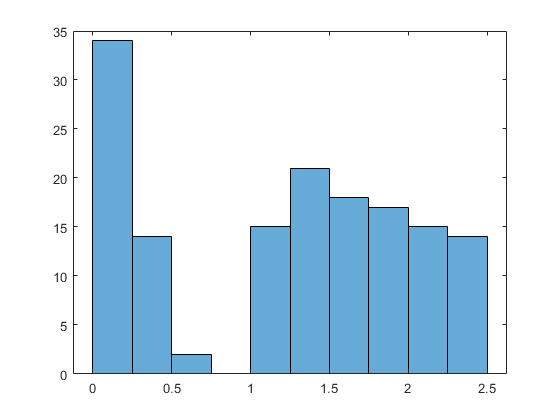

histogram(iris, 10);

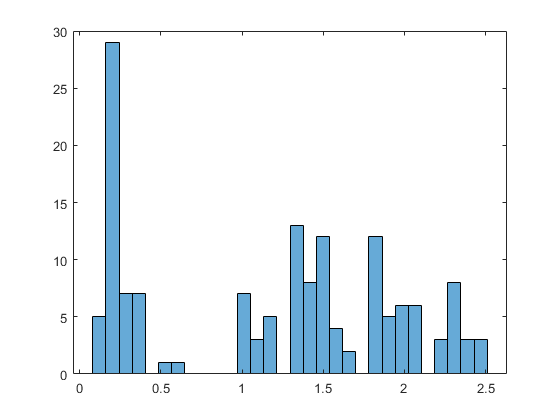

histogram(iris,30);

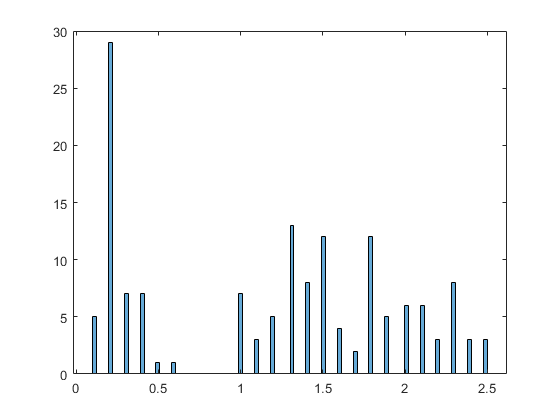

histogram(iris,100);

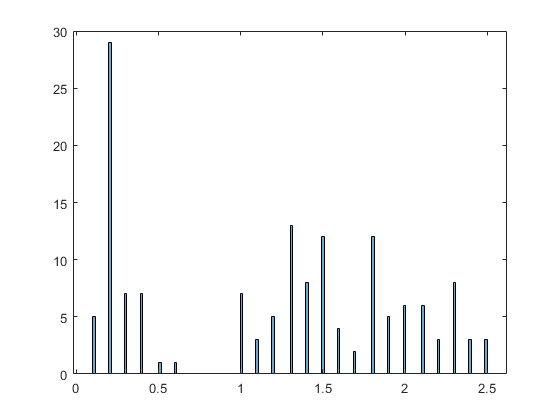

histogram(iris,150);

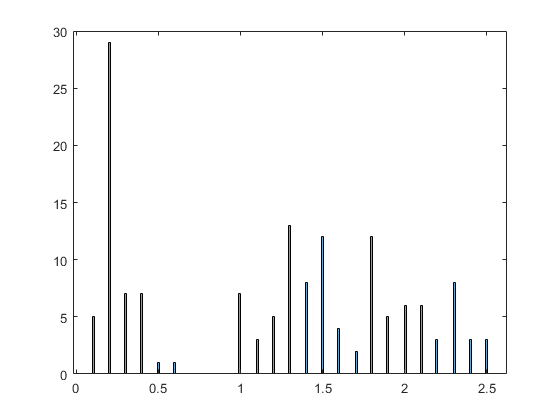

histogram(iris,200);

### Q4

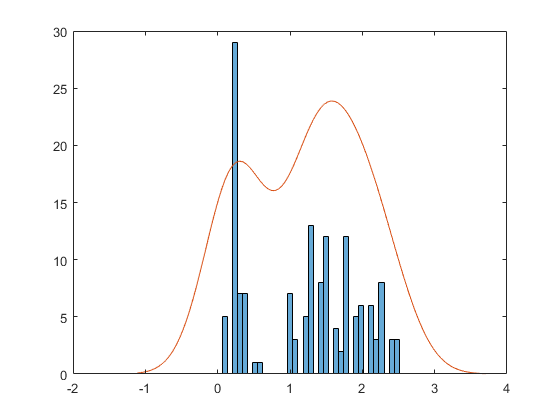

[f, xi, bw] = ksdensity(iris);
histogram(iris, 35);
hold on
plot(xi, 55 .* f);
hold off

Log boundary correction sets

%[f, xi, bw] = ksdensity(iris, 'BoundaryCorrection', 'reflection', 'Support', [0, 3]);
%histogram(iris,35);
%hold on
%plot(xi, 20 .* f);
%hold off
bw

bw = 0.4035

Large bandwidth

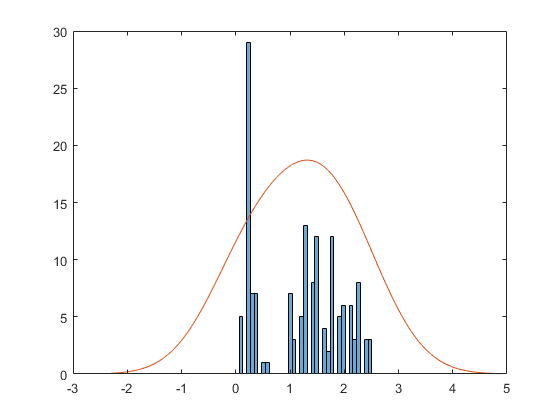

[f, xi] = ksdensity(iris, 'Bandwidth', 0.8);
histogram(iris,35);
hold on
plot(xi, 55 .* f);
hold off

Small bandwidth

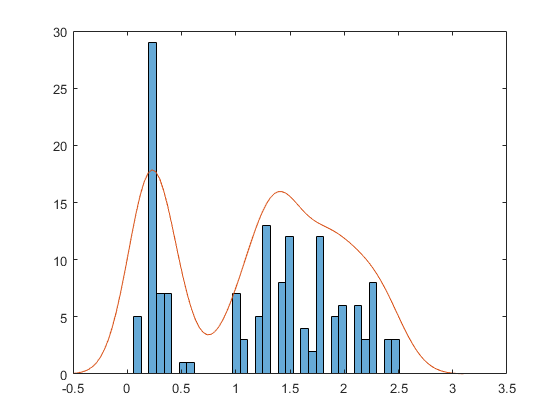

[f, xi] = ksdensity(iris, 'Bandwidth', 0.2);
histogram(iris,35);
hold on
plot(xi, 30 .* f);
hold off

Even smaller bandwidth

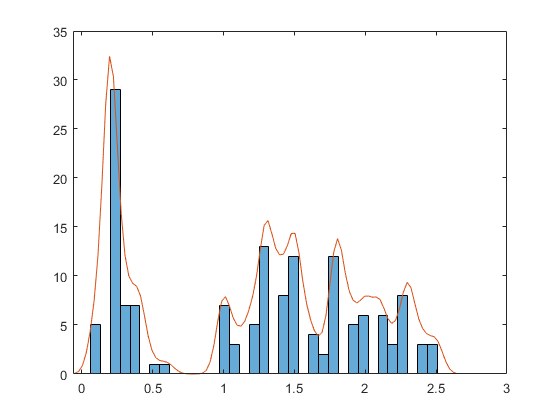

[f, xi] = ksdensity(iris, 'Bandwidth', 0.05);
histogram(iris,35);
hold on
plot(xi, 20 .* f);
hold off

### Q5

Create x data.

x = [randn(30,1); 5+(randn(30,1))];

Fit two kernel density functions to data: one with standard bandwidth, the other with half the standard bandwidth.

[K1, xK1, bw1] = ksdensity(x);
[K2, xK2] = ksdensity(x, 'Bandwidth', bw1/2);

Define domain of data, and evaluate the actual value of the model at each point in the domain.

xtest = linspace(min(x),max(x),100);
M = normpdf(xtest) + normpdf(xtest, 5);

Calculate the KL distance between M and each model. Note that the order of models is important, because they represent a division inside the log.

KLMK1 = sum(0.01.*log(M./K1));
KLMK2 = sum(0.01.*log(M./K2));

Histogram is slightly hard to evaluate at each x-value.

Produce histogram model.

H1 = histcounts(x,20);

Standardise H1 values to sum to 1 (because we're comparing it to probability density functions, while it is a function of counts).

H1 = H1./100;

By defining a domain where H1 is evaluated, we avoid having to do messy code to plot the 100 points onto the bins.

xbins = linspace(min(x),max(x),20);

We then have to define the true model based on the new domain.

MHist = normpdf(xbins) + normpdf(xbins, 5);

Disregard points where the count is zero. If we ignore this, ou KLMH1 becomes infinite.

calculableIndices = H1 ~= 0;
H1 = H1(calculableIndices);
MHist = MHist(calculableIndices);

Calculate our KLMH1 distance.

KLMH1 = sum(0.01.*log(MHist./H1));

Plot each of the models.

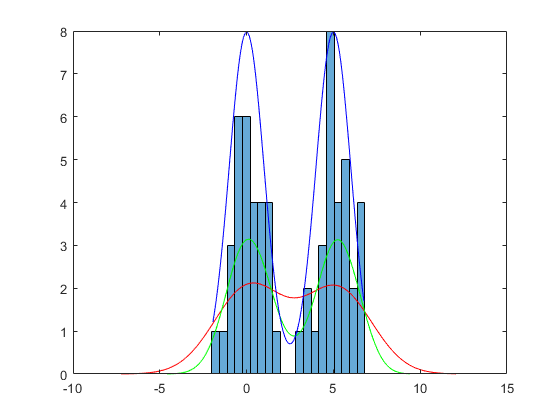

histogram(x,20);
hold on;
plot(xK1, 20.*K1, 'r', xK2, 20.*K2, 'g', xtest, 20.*M, 'b');
hold off;

The true data source is in blue. See how both the red and green lines (K1 and K2 respectively) are far more smoothed than the actual data source. 

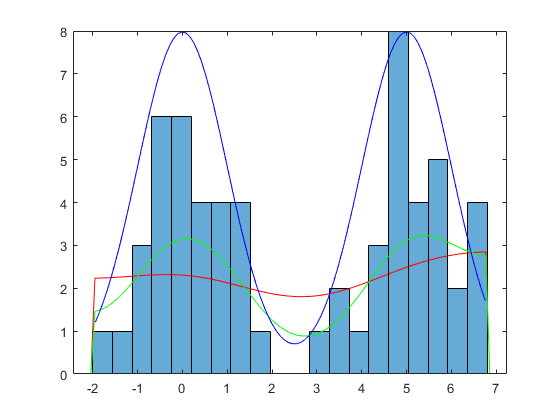

[K1, xK1, bw1] = ksdensity(x, 'Support', [min(x)-0.1, max(x)+0.1], 'BoundaryCorrection', 'reflection');
[K2, xK2] = ksdensity(x, 'Support', [min(x)-0.1, max(x)+0.1], 'BoundaryCorrection', 'reflection', 'Bandwidth', bw1/2);
histogram(x,20);
hold on;
plot(xK1, 20.*K1, 'r', xK2, 20.*K2, 'g', xtest, 20.*M, 'b');
hold off;

Check effect on KL distance.

calculableIndices = K1 ~= 0;
K1calc = K1(calculableIndices);
MK1calc = M(calculableIndices);
KLMK12 = sum(0.01.*log(MK1calc./K1calc));
calculableIndices = K2 ~= 0;
K2calc = K2(calculableIndices);
MK2calc = M(calculableIndices);
KLMK22 = sum(0.01.*log(MK2calc./K2calc));